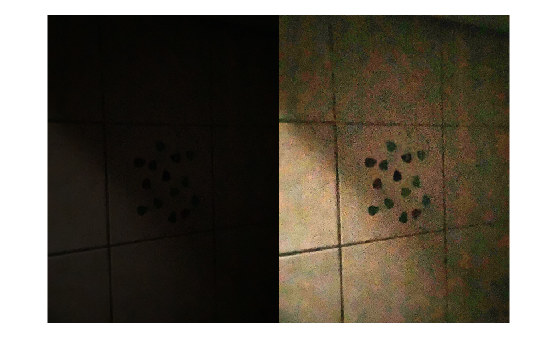

img = imread("picks.jpg");
imgHsv = rgb2hsv(img);
imgHsv(:, :, 3) = imadjust(imgHsv(:, :, 3));
imgHsv(:, :, 3) = adapthisteq(imgHsv(:, :, 3));

imgRgb = hsv2rgb(imgHsv);
imgRgb = im2uint8(imgRgb);

montage({img, imgRgb});

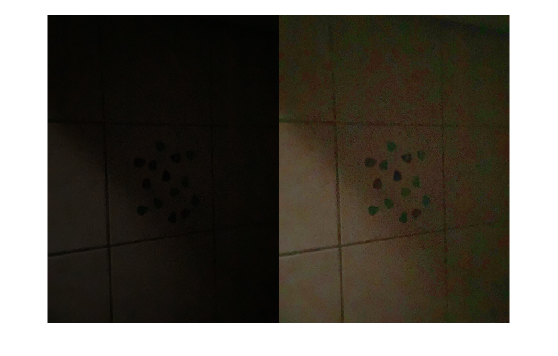

gamma = 0.5;
imgGammaHsv = rgb2hsv(img);
imgGammaHsv(:, :, 3) = im2double(imgGammaHsv(:, :, 3)) .^ gamma;
imgGamma = hsv2rgb(imgGammaHsv);
imgGamma = im2uint8(imgGamma);
montage({img, imgGamma})